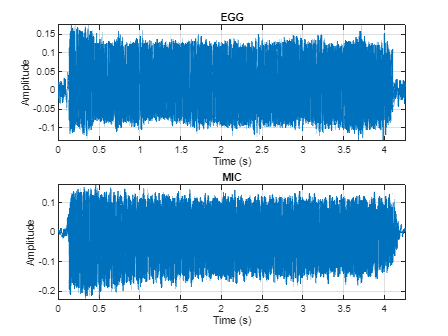

clc, clear
%% Load Data

% PF205_20180101
% This subject has corrupted egg signals
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_soft_a.mat";
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_soft_a-2.mat";
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_loud_a.mat";

% PF217_20180101
%matFile = "E:\code\fulldata\P50\PF217\W1\InLab\MAT calibrated segments\PF217_20180101_soft_a.mat"; % <- A lot of noise in this signal
% I can use this signal as an example of the differences between derivative in time and in frequency with a bandpass
%matFile = "E:\code\fulldata\P50\PF217\W1\InLab\MAT calibrated segments\PF217_20180101_loud_a"; 
%%%%%%%%%%%%%%%%

% NM145_20141231
% noise at 0.8 kHz 
%matFile = "E:\code\fulldata\R33\NM145\W1\InLab\MAT calibrated segments\NM145_20141231_soft_a.mat";
%matFile = "E:\code\fulldata\R33\NM145\W1\InLab\MAT calibrated segments\NM145_20141231_loud_a.mat";

% PF235_20180101
%matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_loud_a.mat"; 
matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_soft_a.mat"; % <- This signal has noise
%matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_speech.mat";

% NF217_20221231

%matFile = "E:\code\fulldata\P50\NF217\W1\InLab\MAT calibrated segments\NF217_20221231_loud_a.mat"; % <- This signal is great for analysis, the GF looks good
%matFile = "E:\code\fulldata\P50\NF217\W1\InLab\MAT calibrated segments\NF217_20221231_soft_a.mat";

data = load(matFile);
fs = data.fs;
mic = data.Mic.Data(:).';
sound = false;
if sound
    soundsc(mic, fs);
end
egg = data.EGG.Data(:)';

show_full = true;  
t_init = 0.2; t_end = 0.35; % Ax limits
plotSignals(egg, "EGG", mic, "MIC", fs, show_full, t_init, t_end)

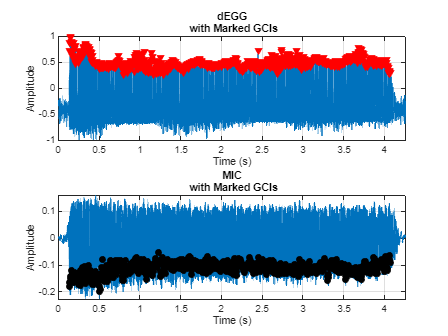

[gcis, degg]= getGCIs(egg, fs);
plotSignalsWithGCIs(degg, "dEGG", mic, "MIC", fs, gcis, show_full, t_init, t_end)

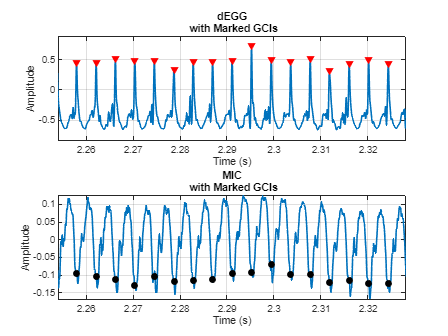

offset = 6;
start_idx = gcis(offset) - 0.0033*fs;
end_idx = gcis(end-offset-1)+ 0.0033*fs;

degg_cut = degg(start_idx:end_idx);
mic_cut = mic(start_idx:end_idx);
gcis_cut = gcis(gcis >= start_idx & gcis <= end_idx) - start_idx + 1;

show_full = true;  
t_init = 0.2; t_end = 0.35; % Ax limits
plotSignalsWithGCIs(degg_cut, "dEGG", mic_cut, "MIC", fs, gcis_cut, show_full, t_init, t_end)

function tmarks = make_tmarks(s, fs, frame_len_ms, frame_shift_ms)
    frame_len = round(frame_len_ms / 1000 * fs);  
    frame_shift = round(frame_shift_ms / 1000 * fs);

    N = length(s);
    starts = 1:frame_shift:(N - frame_len + 1);
    ends = starts + frame_len - 1;

    tmarks = [starts; ends];
end

VTorder   = 20;
GSorder   = 3;
lipRad    = 0.99;
DQ=0.7;PQ=0.1;RQ=0.14;
causality = 'causal';
STcompens = 0;    % 0 = OFF, 1 = ON
tmarks = make_tmarks(mic_cut, fs, 32, 16); 

tic
[G, dG, ~, ~] = qcp_olaf(mic_cut, fs, VTorder, GSorder, lipRad, DQ, PQ, RQ, causality, STcompens, tmarks, gcis_cut);
fprintf('Execution time: %.6f seconds\n', toc);

Execution time: 0.844429 seconds


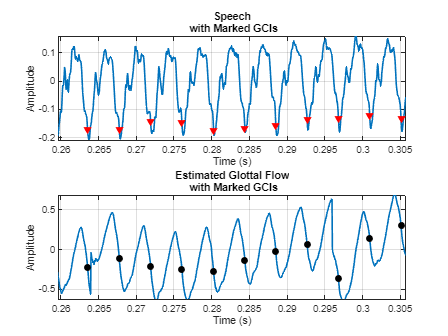

show_full = false;  
t_init = 0.2; t_end = 0.35; 
plotSignalsWithGCIs(mic_cut, "Speech", G, "Estimated Glottal Flow", fs, gcis_cut, show_full, t_init, t_end)

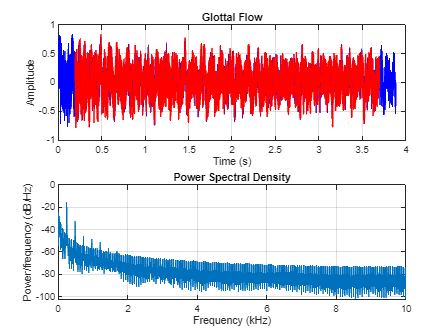

startPercentage = 0.05;
endPercentage = 0.95;
plotPwelch(G,"Glottal Flow", fs, startPercentage, endPercentage)

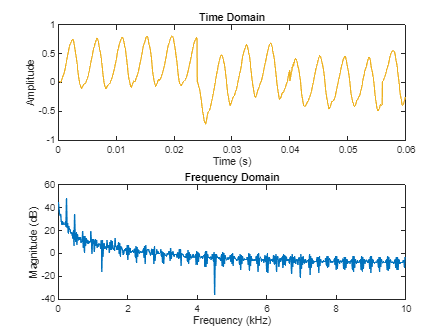

use_time = false;
if use_time
    t_init = 2.95; t_end = 3.25;
    start_idx = round(t_init * fs); end_idx = round(t_end * fs);
else
    start_idx = 1;
    end_idx = round(0.06 * fs);
end

segment = G(start_idx:end_idx);
w = hann(length(segment));
w = ones(length(segment));
segment_windowed = segment(:) .* w;

plotFFT(segment_windowed, fs);

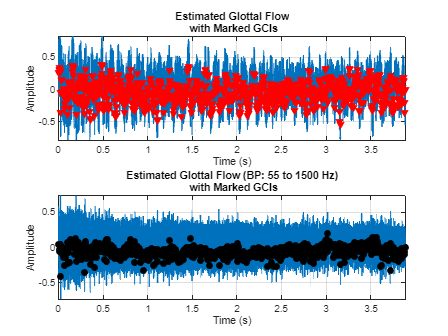

function [y,b] = zeroDelayFIR(x, fs)
N = 1024;
b = fir1(N, [55 1900]/(fs/2), 'bandpass');
y = filtfilt(b, 1, x);
end

[fG,b] = zeroDelayFIR(G, fs);
%figure;
%freqz(b, 1, 1024, fs);

show_full = true;  
t_init = 0.24; t_end = 0.28;
plotSignalsWithGCIs(G, "Estimated Glottal Flow", fG, "Estimated Glottal Flow (BP: 55 to 1500 Hz)", fs, gcis_cut, show_full, t_init, t_end)

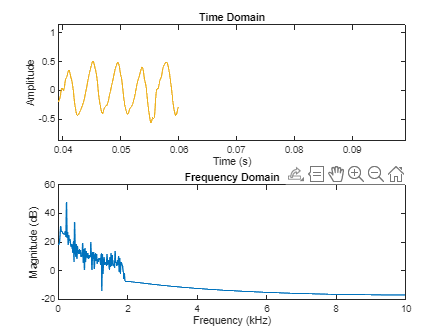

segment = fG(start_idx:end_idx);
w = hann(length(segment));
w = ones(length(segment));
segment_windowed = segment(:) .* w;

plotFFT(segment_windowed, fs);

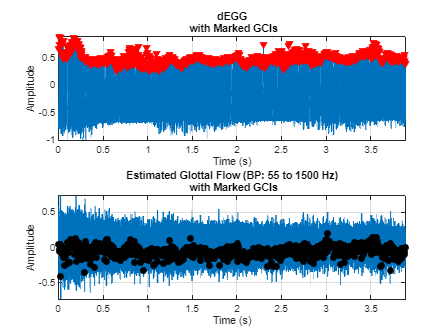

show_full = true;  
t_init = 0.24; t_end = 0.28;
plotSignalsWithGCIs(degg_cut, "dEGG", fG, "Estimated Glottal Flow (BP: 55 to 1500 Hz)", fs, gcis_cut, show_full, t_init, t_end)